# Problema 2

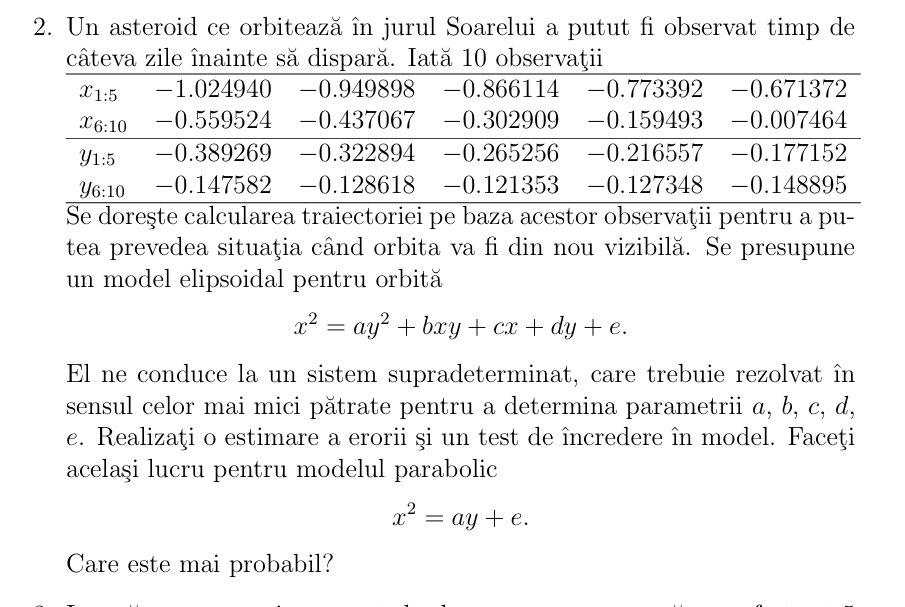

x = [-1.024940, -0.949898, -0.866114, -0.773392, -0.671372, ...
     -0.559524, -0.437067, -0.302909, -0.159493, -0.007464];

y = [-0.389269, -0.322894, -0.265256, -0.216557, -0.177152, ...
     -0.147582, -0.128618, -0.121353, -0.127348, -0.148895];

b = x.^2

b =     1.0505    0.9023    0.7502    0.5981    0.4507    0.3131    0.1910    0.0918    0.0254    0.0001


$x^2 ={\textrm{ay}}^2 +\textrm{bxy}+\textrm{cx}+\textrm{dy}+e$ <-- model elipsoidal (elipsa, parabola, hiperbola sau alte curbe similare)

% Matricea A pentru modelul elipsoidal: 
A_ellip = [y.^2', (x.*y)', x', y', ones(length(x), 1)]

A_ellip =     0.1515    0.3990   -1.0249   -0.3893    1.0000
    0.1043    0.3067   -0.9499   -0.3229    1.0000
    0.0704    0.2297   -0.8661   -0.2653    1.0000
    0.0469    0.1675   -0.7734   -0.2166    1.0000
    0.0314    0.1189   -0.6714   -0.1772    1.0000
    0.0218    0.0826   -0.5595   -0.1476    1.0000
    0.0165    0.0562   -0.4371   -0.1286    1.0000
    0.0147    0.0368   -0.3029   -0.1214    1.0000
    0.0162    0.0203   -0.1595   -0.1273    1.0000
    0.0222    0.0011   -0.0075   -0.1489    1.0000



% Rezolvam sistemul A * coef = b
coef_ellip = A_ellip \ b'; % ERONAT

disp('Coeficientii modelului elipsoidal [a, b, c, d, e]:\n');

Coeficientii modelului elipsoidal [a, b, c, d, e]:\n


disp(coef_ellip');

   -1.3026   -0.7160   -0.6793   -3.3790   -0.4782




% Aproximam valorile x^2 pe baza coeficientilor
b_aprox_ellip = A_ellip * coef_ellip;

% Calculam eroarea (suma patratelor diferentelor)
eroare_ellip = sum((b' - b_aprox_ellip).^2);
fprintf('Eroare totala model elipsoidal: %.10f\n\n', eroare_ellip);

Eroare totala model elipsoidal: 0.0000012064



$x^2 =\textrm{ay}+e$ <-- model parabolic

% Matrice pentru modelul parabolic: 
A_parab = [y', ones(length(y), 1)]

A_parab =    -0.3893    1.0000
   -0.3229    1.0000
   -0.2653    1.0000
   -0.2166    1.0000
   -0.1772    1.0000
   -0.1476    1.0000
   -0.1286    1.0000
   -0.1214    1.0000
   -0.1273    1.0000
   -0.1489    1.0000



% Rezolvam sistemul A_parab * coef = b
coef_parab = A_parab \ b';

% Afisam coeficientii
fprintf('Coeficientii modelului parabolic [a, e]:\n');

Coeficientii modelului parabolic [a, e]:


disp(coef_parab');

   -3.8549   -0.3510




% Calculam aproximarea si eroarea
b_aprox_parab = A_parab * coef_parab;
eroare_parab = sum((b' - b_aprox_parab).^2);
fprintf('Eroare totala model parabolic: %.10f\n\n', eroare_parab);

Eroare totala model parabolic: 0.1178826209



% Comparam modelele
if eroare_ellip < eroare_parab
    fprintf('Modelul ELIPSOIDAL este mai precis.\n');
else
    fprintf('Modelul PARABOLIC este mai precis.\n');
end

Modelul ELIPSOIDAL este mai precis.
